# Generator parameter calculation with aggregation

Generator parameter calculation using NYISO Gold book data and USEPA RGGI data. Aggregation of small generator are performed.

## Parameter calculation of matched generators

### Import the data

#### Import the RGGI generation data

% Import hourly generation data of generators in RGGI database in the 2019 whole year
genFileDir = "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\EPA_RGGI\2019\";
genFileName = "emission*.csv";
genDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
genAll = readall(genDataStore);
clear genDataStore;

#### Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
generatorCombiner = importRefTable("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\RGGI_2_NYCA_2019.xlsx");
% Exclude generators with total generation less than 1
generatorCombiner = generatorCombiner(generatorCombiner.NetEnergyGWh >= 1, :);

% Create arrays of key features
NYISONames = unique(generatorCombiner.NYISOName);
PTIDs = unique(generatorCombiner.PTID);
unitTypes = unique(generatorCombiner.UnitType);
fuelTypes = unique(generatorCombiner.FuelType);
Zones = unique(generatorCombiner.Zone);
numGenMatched = size(PTIDs, 1)

numGenMatched =    137


#### Group summary of nameplate capacity in NYCA database

% Group summary of nameplate capacity by unit type and fuel type
unitFuelTypeSummary = groupsummary(generatorCombiner, ["UnitType", "FuelType"] , "sum", ["NamePlateRatingMW", "GrossLoadMWh"]);
total_count = sum(unitFuelTypeSummary.GroupCount);
total_cap = sum(unitFuelTypeSummary.sum_NamePlateRatingMW);
total_gen = sum(unitFuelTypeSummary.sum_GrossLoadMWh);
unitFuelTypeSummary.capPer = unitFuelTypeSummary.sum_NamePlateRatingMW/total_cap;
unitFuelTypeSummary.genPer = unitFuelTypeSummary.sum_GrossLoadMWh/total_gen;
unitFuelTypeSummary.Properties.VariableNames = ["unitType", "fuelType", "Count", "totalCapacity", "totalGeneration", "capPercent", "genPercent"]

unitFuelTypeSummary = 9×7 table
         unitType          fuelType      Count    totalCapacity    totalGeneration        capPercent             genPercent     
    __________________    ___________    _____    _____________    _______________    __________________    ____________________

    Combined Cycle        Natural Gas     59         18153.8         37179583.89       0.531232259386065       0.796455543836979
    Combustion Turbine    Fuel Oil         8           500.9            21659.55      0.0146577707546894    0.000463987674675243
    Combustion Turbine    Natural Gas     29          1229.8          1110990.55      0.0359874754923478      0.0237994751451747
    Jet Engine            Fuel Oil        10           564.3            35849.59    

unitTypeSummary = groupsummary(unitFuelTypeSummary, "unitType", "sum", ["Count","totalCapacity", "capPercent", "totalGeneration", "genPercent"]);
unitTypeSummary = removevars(unitTypeSummary, "GroupCount");
unitTypeSummary.Properties.VariableNames = ["unitType", "Count", "totalCapacity", "capPercent", "totalGeneration", "genPercent"]

unitTypeSummary = 4×6 table
         unitType         Count    totalCapacity        capPercent        totalGeneration        genPercent     
    __________________    _____    _____________    __________________    _______________    ___________________

    Combined Cycle         59         18153.8        0.531232259386065      37179583.89        0.796455543836979
    Combustion Turbine     37          1730.7       0.0506452462470371        1132650.1         0.02426346281985
    Jet Engine             36          1801.3       0.0527112047522898        189464.62      0.00405868305052638
    Steam Turbine          31         12487.2        0.365411289614608       8179606.05        0.175222310292645


fuelTypeSummary = groupsummary(unitFuelTypeSummary, "fuelType", "sum", ["Count","totalCapacity", "capPercent", "totalGeneration", "genPercent"]);
fuelTypeSummary = removevars(fuelTypeSummary, "GroupCount");
fuelTypeSummary.Properties.VariableNames = ["fuelType", "Count", "totalCapacity", "capPercent", "totalGeneration", "genPercent"]

fuelTypeSummary = 4×6 table
     fuelType      Count    totalCapacity        capPercent        totalGeneration        genPercent     
    ___________    _____    _____________    __________________    _______________    ___________________

    Coal              2          810.4       0.0237146285078863        472135.28       0.0101140120962506
    Fuel Oil         31         7839.8        0.229415035261756       2821278.11       0.0604370021478316
    Kerosene         25         1176.5        0.034427764609487         26821.33      0.00057456256193676
    Natural Gas     105        24346.3         0.71244257162087      43361069.94        0.928874423193981


#### Combine the generation table with the reference table

% Combine the RGGI database with the NYCA database
% Join tables
genAllJoint = innerjoin(genAll,generatorCombiner,'Keys',{'FacilityName','FacilityID','UnitID'}, ...
    'LeftVariables', {'FacilityName','FacilityID', 'UnitID', 'Date', 'Hour', 'GrossLoadMW', 'HeatInputMMBtu'}, ...
    "RightVariables", {'NYISOName', 'PTID', 'Zone', 'UnitType', 'FuelType', 'Combined'});

### Generator feature calculation

#### Calculate feature for each generator

% Define arrays to record NYISO generators' parameter
% We define a generator by its PTID. 147 generators.
% Different generator could have same NYISO name.
% One PTID could correspond to multiple units in the RGGI database.
maxPower = zeros(numGenMatched, 1);
minPower = zeros(numGenMatched, 1);
maxHeat = zeros(numGenMatched, 1);
minHeat = zeros(numGenMatched, 1);
maxRampUp = zeros(numGenMatched, 1);
maxRampDown = zeros(numGenMatched, 1);
HeatRateLM = zeros(numGenMatched, 2);
HeatRateQM = zeros(numGenMatched, 3);
HeatRateLMR2 = zeros(numGenMatched, 1);
HeatRateQMR2 = zeros(numGenMatched, 1);
hourlyGenFilteredTables = cell(numGenMatched, 1);

for i=1:numGenMatched
    % Subset generation table by PTID
    PTID = PTIDs(i);
    genSet = genAllJoint(genAllJoint.PTID == PTID, :);
    hourlyGen = groupsummary(genSet, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
    % Calculate ramp rate
    rampRate = hourlyGen.sum_GrossLoadMW(2:end) - hourlyGen.sum_GrossLoadMW(1:end-1);
    hourlyGen.RampRate = [0; rampRate];
    % Exclude hours with zero generation, also exclude ramp down to zero
    hourlyGenNZ = hourlyGen(hourlyGen.sum_GrossLoadMW > 0, :);
    % Calcualte max output and min output (lowest 10%)
    lowPercent = 10;
    highPercent = 100;
    [genOutIdx,genPer10,genMax,genMedian] = isoutlier(hourlyGenNZ.sum_GrossLoadMW,"percentiles", [lowPercent, highPercent]);
    [heatOutIdx,heatPer10,heatMax,heatMedian] = isoutlier(hourlyGenNZ.sum_HeatInputMMBtu,"percentiles", [lowPercent, highPercent]);
    genHeatOutIdx = genOutIdx|heatOutIdx;
    hourlyGenNZFiltered = hourlyGenNZ(~genHeatOutIdx, :);
    % Fit linear model of heat rate
    genHeatLM = fitlm(hourlyGenNZFiltered, "sum_HeatInputMMBtu ~ 1 + sum_GrossLoadMW");
    HeatRateLMR2(i) = genHeatLM.Rsquared.Adjusted;
    HeatRateLM(i, :) = genHeatLM.Coefficients.Estimate.';
    hourlyGenNZFiltered.HeatRateLMFit = genHeatLM.Fitted;
    % Fit quadratic model of heat rate
    genHeatQM = fitlm(hourlyGenNZFiltered, "sum_HeatInputMMBtu ~ 1 + sum_GrossLoadMW + sum_GrossLoadMW^2");
    HeatRateQMR2(i) = genHeatQM.Rsquared.Adjusted;
    HeatRateQM(i, :) = genHeatQM.Coefficients.Estimate.';
    hourlyGenNZFiltered.HeatRateQMFit = genHeatQM.Fitted;
    % Store the results    
    maxPower(i) = genMax;
    minPower(i) = genPer10;
    maxRampUp(i) = max(hourlyGenNZFiltered.RampRate);
    maxRampDown(i) = min(hourlyGenNZFiltered.RampRate);
    hourlyGenFilteredTables{i} = hourlyGenNZFiltered;
end

% Combine generator parameters into one summary table
maxRamp60 = (maxRampUp + abs(maxRampDown))/2;
maxRamp30 = maxRamp60/2;
maxRamp10 = maxRamp30/3;
maxRampAgc = maxRamp10/10;
paramSummary = table(PTIDs, maxPower, minPower, maxRampAgc, maxRamp10, maxRamp30, maxRamp60, HeatRateLM, HeatRateLMR2, HeatRateQM, HeatRateQMR2);
paramSummary.Properties.VariableNames(1) = "PTID";

% Remove duplicated generator names in the generator combiner (multiple RGGI generators with the same PTID)
genComNoDup = generatorCombiner(generatorCombiner.Combined == "0", ["NYISOName", "PTID", "Zone", "UnitType", "FuelType", "NamePlateRatingMW", "CapabilitySummerMW", "CapabilityWinterMW"]);
genComDup = generatorCombiner(generatorCombiner.Combined == "1", ["NYISOName", "PTID", "Zone", "UnitType", "FuelType", "NamePlateRatingMW", "CapabilitySummerMW", "CapabilityWinterMW"]);
genComDupRed = unique(genComDup, 'rows');
genComRed = [genComNoDup; genComDupRed];

#### Combine the calculated parameters to other NYISO generator info

% Add generator information to the generator summary table
paramSummaryJoint = outerjoin(paramSummary,genComRed,'Type','left','LeftKeys',{'PTID'},'RightKeys',{'PTID'}, ...
    "LeftVariables", {'maxPower', 'minPower', 'maxRampAgc','maxRamp10','maxRamp30', 'maxRamp60','HeatRateLM','HeatRateLMR2','HeatRateQM','HeatRateQMR2'}, ...
    "RightVariables",{'NYISOName', 'PTID', 'Zone', 'NamePlateRatingMW', 'CapabilitySummerMW', 'CapabilityWinterMW','UnitType', 'FuelType'});
paramSummaryJoint = movevars(paramSummaryJoint, ["NYISOName", 'PTID', "UnitType", "FuelType", "Zone", "NamePlateRatingMW"], "Before", "maxPower")

paramSummaryJoint = 137×18 table
        NYISOName         PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc           maxRamp10        maxRamp30    maxRamp60                  HeatRateLM                    HeatRateLMR2                                  HeatRateQM                                  HeatRateQMR2       CapabilitySummerMW    CapabilityWinterMW
    __________________    _____    __________________    ___________    ____    _________________    ________    ________    ______

### Heat rate bad fitting results analysis

#### Show bad fit results

% Select R2 below 0.85 bad fit results
R2Limit = 0.8;
badFitIdx = paramSummaryJoint.HeatRateLMR2 < R2Limit;
badFitNum = nnz(badFitIdx)

badFitNum =     25


badFitTable = paramSummaryJoint(badFitIdx, :);
goodFitTable = paramSummaryJoint(~badFitIdx, :);
badFitData = hourlyGenFilteredTables(badFitIdx);

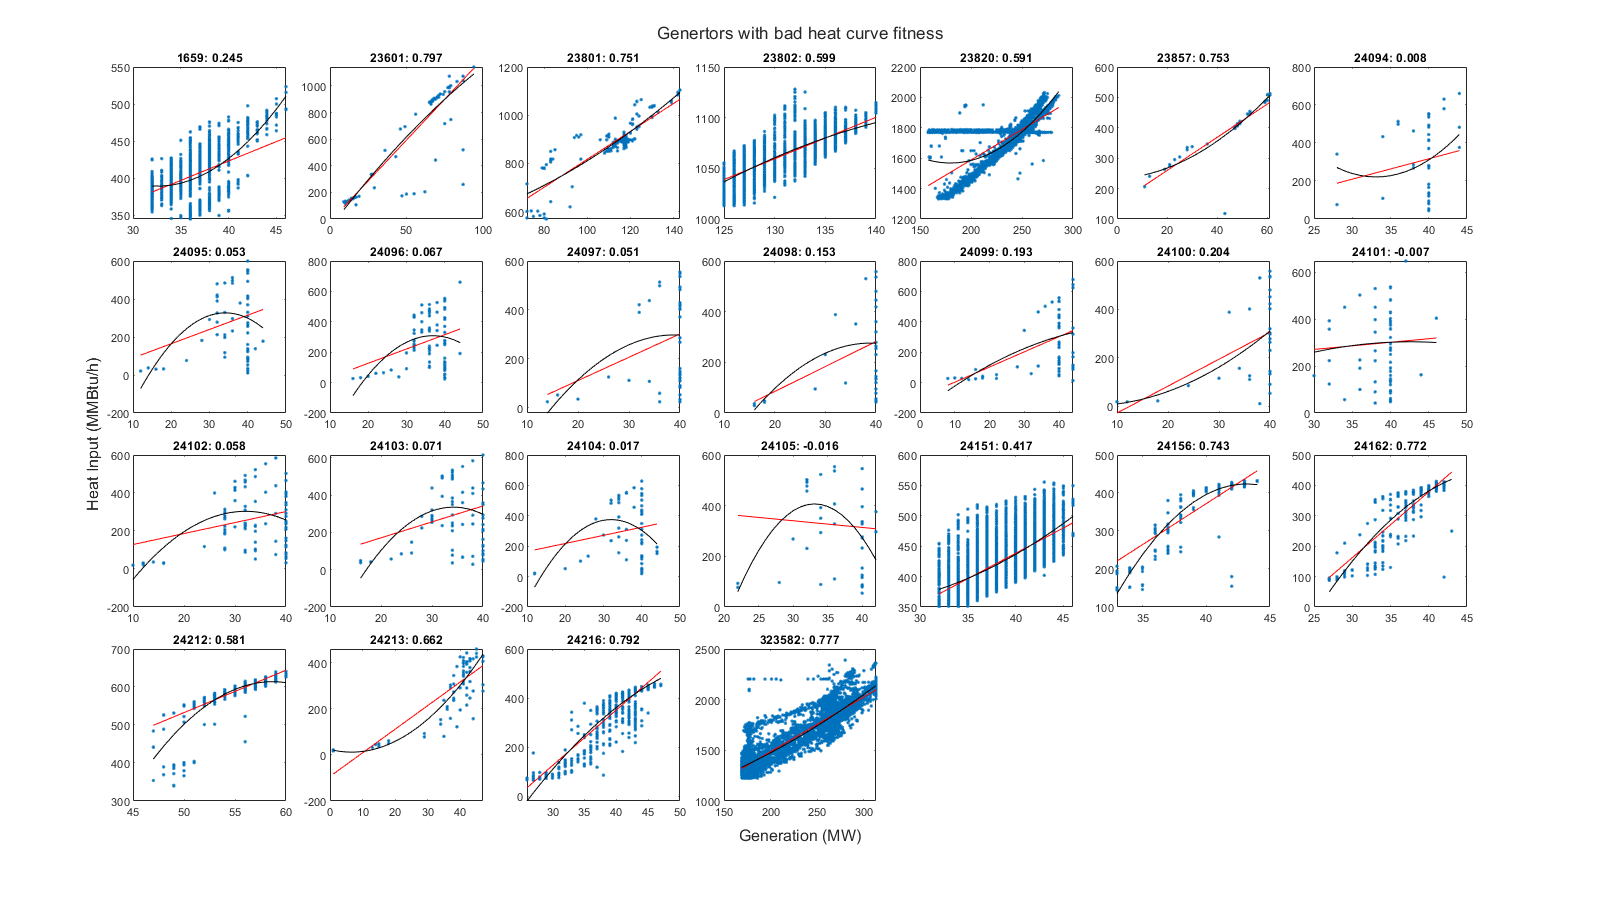

colNum = 7;
rowNum = int16(badFitNum/colNum);
t = tiledlayout(rowNum, colNum, "TileSpacing","compact");
for n=1:badFitNum
    nexttile;
    badFitPTID = badFitTable(n, :).PTID;
    badFitName = badFitTable(n, :).NYISOName;
    badFitLMR2 = badFitTable(n, :).HeatRateLMR2;
    badFitLMCoef = badFitTable(n, :).HeatRateLM;
    badFitQMCoef = badFitTable(n, :).HeatRateQM;
    badFitDataTable = badFitData{n};
%     badFitPTID = badFitPTIDs(n);
%     badFitLMR2 = badFitLMR2s(n);
%     badFitTable = badFitFilteredTables{n};
%     badFitLMCoef = badFitLMCoefs(n, :);
%     badFitQMCoefQM = badFitQMCoefs(n, :);
    scatter(badFitDataTable.sum_GrossLoadMW, badFitDataTable.sum_HeatInputMMBtu, '.');
    hold on;
    generation = min(badFitDataTable.sum_GrossLoadMW): max(badFitDataTable.sum_GrossLoadMW);
    plot(generation, badFitLMCoef(1) + badFitLMCoef(2).*generation, 'r-');
    plot(generation, badFitQMCoef(1) + badFitQMCoef(2).*generation + badFitQMCoef(3).*generation.^2, 'k-');
    hold off; box on;
    txt = sprintf("%s: %.3f", badFitPTID, badFitLMR2);
    title(txt);
end
xlabel(t, "Generation (MW)");
ylabel(t, "Heat Input (MMBtu/h)");
title(t, "Genertors with bad heat curve fitness");

set(gcf, "Position", [50, 50, 1600, 900]);

badAllIdx = (badFitTable.HeatRateLMR2) <= 0.7 & (badFitTable.HeatRateQMR2 <= 0.7);
gt100Idx = badFitTable.maxPower >= 100;
% Subset bad fit table
badFitGt100Bad = badFitTable((badAllIdx) & (gt100Idx), :) % Large CC， not sure what to do, use fitted function for now

badFitGt100Bad = 2×18 table
       NYISOName        PTID        UnitType        FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc           maxRamp10        maxRamp30    maxRamp60                 HeatRateLM                   HeatRateLMR2                                 HeatRateQM                                 HeatRateQMR2       CapabilitySummerMW    CapabilityWinterMW
    ________________    _____    ______________    ___________    ____    _________________    ________    ________    _________________ 

badFitLt100Bad = badFitTable((badAllIdx) & (~gt100Idx), :) % Small JE and CT, treat as direct ramp units

badFitLt100Bad = 14×18 table
          NYISOName           PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc           maxRamp10        maxRamp30    maxRamp60                  HeatRateLM                     HeatRateLMR2                                 HeatRateQM                                 HeatRateQMR2        CapabilitySummerMW    CapabilityWinterMW
    ______________________    _____    __________________    ___________    ____    _________________    ________    ________    __

badFitGt100LM = badFitTable((~badAllIdx) & gt100Idx, :) % Not too bad, still use fitted function

badFitGt100LM = 2×18 table
            NYISOName             PTID        UnitType        FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc          maxRamp10        maxRamp30    maxRamp60                 HeatRateLM                   HeatRateLMR2                                 HeatRateQM                                HeatRateQMR2       CapabilitySummerMW    CapabilityWinterMW
    _________________________    ______    ______________    ___________    ____    _________________    ________    ________    __________

badFitLt100LM = badFitTable((~badAllIdx) & (~gt100Idx), :) % Not too bad, still use fitted function

badFitLt100LM = 7×18 table
       NYISOName        PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc           maxRamp10        maxRamp30    maxRamp60                  HeatRateLM                    HeatRateLMR2                                 HeatRateQM                                 HeatRateQMR2       CapabilitySummerMW    CapabilityWinterMW
    ________________    _____    __________________    ___________    ____    _________________    ________    ________    _________________<

#### Modify parameter table due to bad fitting

% Set min power as zero
% Set max hourly ramp rate as max power (instant ramp to maximum)
badFitChanged = badFitLt100Bad;
numBadFitChanged = height(badFitChanged);
badFitUnchanged = [badFitGt100Bad; badFitGt100LM; badFitLt100LM];
badFitChanged.minPower = zeros(numBadFitChanged, 1);
badFitChanged.maxRampAgc = badFitChanged.maxPower./60;
badFitChanged.maxRamp10 = badFitChanged.maxPower./6;
badFitChanged.maxRamp30 = badFitChanged.maxPower./2;
badFitChanged.maxRamp60 = badFitChanged.maxPower;
% 1 MMBtu = 0.293 MWh, assume 25% efficiency, resulting 13.652 MMBtu/MWh
% EIA 2019 GT: 11098 Btu/kWh = 11.098 MMBtu/MWh
badFitChanged.HeatRateLM = repmat([0, 13.652], numBadFitChanged, 1);
badFitChanged.HeatRateLMR2 = zeros(numBadFitChanged, 1);
badFitChanged.HeatRateQM = zeros(numBadFitChanged, 3);
badFitChanged.HeatRateQMR2 = zeros(numBadFitChanged, 1);

#### Final version of the matched generator parameter table

paramMatchedFinal = [goodFitTable; badFitUnchanged; badFitChanged];
paramMatchedFinal.HeatRateLM_1 = paramMatchedFinal.HeatRateLM(:, 1);
paramMatchedFinal.HeatRateLM_2 = paramMatchedFinal.HeatRateLM(:, 2);
paramMatchedFinal = removevars(paramMatchedFinal, ["CapabilitySummerMW","CapabilityWinterMW","HeatRateLM","HeatRateQM","HeatRateQMR2"]);
paramMatchedFinal = movevars(paramMatchedFinal, "HeatRateLMR2","After","HeatRateLM_2")

paramMatchedFinal = 137×15 table
        NYISOName         PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc           maxRamp10        maxRamp30    maxRamp60      HeatRateLM_1         HeatRateLM_2        HeatRateLMR2   
    __________________    _____    __________________    ___________    ____    _________________    ________    ________    _________________    ________________    _________    _________    _________________    ________________

## Parameter calculation of unmatched generators

### Import unmatched generator data

genNotMatched = importNotMatched("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\2019_NYCA_Not_Matched.xlsx");

### Generator data cleaning

% Exclude generators with total generation less than 1 GWh
genNMFiltered = genNotMatched(genNotMatched.NetEnergyGWh >= 1, :);
% Exclude methane (Bio gas)
genNMFiltered = genNMFiltered(genNMFiltered.FuelType ~= "Methane", :);
% genNMSmall= genNMFiltered(genNMFiltered.NamePlateRatingMW >= 40, :)
% genNMLarge = genNMFiltered(genNMFiltered.NamePlateRatingMW < 40, :)

### Calculate generator parameters

paramUnmatched = removevars(genNMFiltered, ["NetEnergyGWh","CRISSummerMW","CRISWinterMW","CapabilitySummerMW","CapabilityWinterMW"]);
paramUnmatched = movevars(paramUnmatched, ["Zone", "NamePlateRatingMW"], "After", "FuelType");
numNMGen = size(paramUnmatched, 1);
paramUnmatched.maxPower = paramUnmatched.NamePlateRatingMW;
paramUnmatched.minPower = zeros(numNMGen, 1);
paramUnmatched.maxRampAgc = paramUnmatched.maxPower./60;
paramUnmatched.maxRamp10 = paramUnmatched.maxPower./6;
paramUnmatched.maxRamp30 = paramUnmatched.maxPower./2;
paramUnmatched.maxRamp60 = paramUnmatched.maxPower;
paramUnmatched.HeatRateLM_1 = zeros(numNMGen, 1);
% Heat rate data from EIA 2019
for n = 1:numNMGen
    unitType = paramUnmatched.UnitType(n);
    fuelType = paramUnmatched.FuelType(n);
    switch unitType
        case "Combined Cycle"
            switch fuelType
                case {"Natural Gas","Kerosene"}
                    paramUnmatched.HeatRateLM_2(n) = 7.633;
                case "Fuel Oil"
                    paramUnmatched.HeatRateLM_2(n) = 9.662;
            end
        
        case {"Combustion Turbine", "Jet Engine"}
            switch fuelType
                case {"Natural Gas","Kerosene"}
                    paramUnmatched.HeatRateLM_2(n) = 11.098;
                case "Fuel Oil"
                    paramUnmatched.HeatRateLM_2(n) = 13.315;
            end
            
         case "Internal Combustion"
            switch fuelType
                case {"Natural Gas","Kerosene"}
                    paramUnmatched.HeatRateLM_2(n) = 8.899;
                case "Fuel Oil"
                    paramUnmatched.HeatRateLM_2(n) = 10.325;
            end
        case "Steam Turbine"
            switch fuelType
                case {"Natural Gas","Kerosene"}
                    paramUnmatched.HeatRateLM_2(n) = 10.347;
                case "Fuel Oil"
                    paramUnmatched.HeatRateLM_2(n) = 10.236;
                case "Coal"
                    paramUnmatched.HeatRateLM_2(n) = 10.002;
            end
    end
end

paramUnmatched.HeatRateLMR2 = zeros(numNMGen, 1);
paramUnmatched

paramUnmatched = 40×15 table
            NYISOName            PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc           maxRamp10        maxRamp30    maxRamp60    HeatRateLM_1    HeatRateLM_2    HeatRateLMR2
    _________________________    _____    __________________    ___________    ____    _________________    ________    ________    _________________    ________________    _________    _________    ____________    ____________    

## Generator parameter final results

### Combine the matched and unmatched generators' parameter

paramAll = [paramMatchedFinal; paramUnmatched]

paramAll = 177×15 table
        NYISOName         PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc           maxRamp10        maxRamp30    maxRamp60      HeatRateLM_1         HeatRateLM_2        HeatRateLMR2   
    __________________    _____    __________________    ___________    ____    _________________    ________    ________    _________________    ________________    _________    _________    _________________    ________________   

### Generator aggregation

#### Find the generators with capacity less than 100 MW and aggregate them

capThres = 100;
paramLarge = paramAll(paramAll.maxPower > capThres, :);
paramSmall = paramAll(paramAll.maxPower <= capThres, :);
paramSmallSum = groupsummary(paramSmall, ["Zone","UnitType","FuelType"])

paramSmallSum = 20×4 table
    Zone         UnitType          FuelType      GroupCount
    ____    __________________    ___________    __________

     A      Combined Cycle        Natural Gas         3    
     A      Combustion Turbine    Natural Gas         2    
     A      Steam Turbine         Natural Gas         1    
     B      Combined Cycle        Natural Gas         2    
     C      Combined Cycle        Natural Gas         4    
     D      Combined Cycle        Natural Gas         1    
     E      Combined Cycle        Natural Gas         3    
     F      Combined Cycle        Natural Gas         2    
     G      Steam Turbine         Natural Gas         2    
     J      Combined Cycle        Natural Gas         2    
     J      Combustion Turbine    Fuel Oil           24    
     J      Combustion Turbine    Natural Gas        12 

#### Create subsets of generators that will be aggregated

numAggGroup = height(paramSmallSum);
paramSmallGroups = cell(numAggGroup);
for n=1:numAggGroup
    zone = paramSmallSum.Zone(n);
    unitType = paramSmallSum.UnitType(n);
    fuelType = paramSmallSum.FuelType(n);
    genGroup = paramSmall(paramSmall.Zone == zone & paramSmall.UnitType == unitType & paramSmall.FuelType == fuelType, :);
    paramSmallGroups{n} = genGroup;
end

#### Calculate aggregated generator parameters of each subset

Aggregation methods:

- max power: sum of max power of individual generators

- min power: min of min power of individual generators

- ramp rate: weighted average of ramp rate of individual generators, weighted by max power

- heat rate: use heat rate data from US EIA [SAS Output (eia.gov)](https://www.eia.gov/electricity/annual/html/epa_08_02.html)

paramSmallAgg = removevars(paramSmallSum, "GroupCount");
for n=1:numAggGroup
    genGroup = paramSmallGroups{n};
    zone = paramSmallSum.Zone(n);
    unitType = paramSmallSum.UnitType(n);
    fuelType = paramSmallSum.FuelType(n);
    paramSmallAgg.NYISOName(n) = strcat("Agg-",string(zone),"-",string(unitType),"-",string(fuelType));
    paramSmallAgg.PTID(n) = "";
    paramSmallAgg.NamePlateRatingMW(n) = sum(genGroup.NamePlateRatingMW);
    paramSmallAgg.maxPower(n) = sum(genGroup.maxPower);
    paramSmallAgg.minPower(n) = min(genGroup.minPower);
    paramSmallAgg.maxRampAgc(n) = round(sum(genGroup.maxPower.*genGroup.maxRampAgc)/sum(genGroup.maxPower),3);
    paramSmallAgg.maxRamp10(n) = paramSmallAgg.maxRampAgc(n)*10;
    paramSmallAgg.maxRamp30(n) = paramSmallAgg.maxRampAgc(n)*30;
    paramSmallAgg.maxRamp60(n) = paramSmallAgg.maxRampAgc(n)*60;
    paramSmallAgg.HeatRateLM_1(n) = 0;
    switch unitType
        case "Combined Cycle"
            switch fuelType
                case {"Natural Gas","Kerosene"}
                    paramSmallAgg.HeatRateLM_2(n) = 7.633;
                case "Fuel Oil"
                    paramSmallAgg.HeatRateLM_2(n) = 9.662;
            end
        
        case {"Combustion Turbine", "Jet Engine"}
            switch fuelType
                case {"Natural Gas","Kerosene"}
                    paramSmallAgg.HeatRateLM_2(n) = 11.098;
                case "Fuel Oil"
                    paramSmallAgg.HeatRateLM_2(n) = 13.315;
            end
            
         case "Internal Combustion"
            switch fuelType
                case {"Natural Gas","Kerosene"}
                    paramSmallAgg.HeatRateLM_2(n) = 8.899;
                case "Fuel Oil"
                    paramSmallAgg.HeatRateLM_2(n) = 10.325;
            end
        case "Steam Turbine"
            switch fuelType
                case {"Natural Gas","Kerosene"}
                    paramSmallAgg.HeatRateLM_2(n) = 10.347;
                case "Fuel Oil"
                    paramSmallAgg.HeatRateLM_2(n) = 10.236;
                case "Coal"
                    paramSmallAgg.HeatRateLM_2(n) = 10.002;
            end
    end
    paramSmallAgg.HeatRateLMR2(n) = 0;
end
paramSmallAgg = movevars(paramSmallAgg, ["NYISOName","PTID","UnitType","FuelType"], "Before", "Zone");
paramSmallAgg.NYISOName = categorical(paramSmallAgg.NYISOName);
paramSmallAgg.PTID = categorical(paramSmallAgg.PTID);

paramLarge

paramLarge = 55×15 table
        NYISOName         PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc          maxRamp10        maxRamp30    maxRamp60      HeatRateLM_1        HeatRateLM_2        HeatRateLMR2   
    __________________    _____    __________________    ___________    ____    _________________    ________    ________    ________________    ________________    _________    _________    ________________    ________________    <s

paramSmallAgg

paramSmallAgg = 20×15 table
                 NYISOName                     PTID             UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60    HeatRateLM_1    HeatRateLM_2    HeatRateLMR2
    ____________________________________    ___________    __________________    ___________    ____    _________________    ________    ________    __________    _________    _________    _________    ____________    ____________  

paramFinal = [paramLarge; paramSmallAgg]

paramFinal = 75×15 table
        NYISOName         PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower       maxRampAgc          maxRamp10        maxRamp30    maxRamp60      HeatRateLM_1        HeatRateLM_2        HeatRateLMR2   
    __________________    _____    __________________    ___________    ____    _________________    ________    ________    ________________    ________________    _________    _________    ________________    ________________    <s

### Write parameter table of the matched generators

writetable(paramFinal, "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\genParamFinal.csv");